# Numerical Methods for Optimization and Control Theory

## Assignment 1 - Daniel Kuknyo

Tasks assigned: 2, 5, 7, 13

## 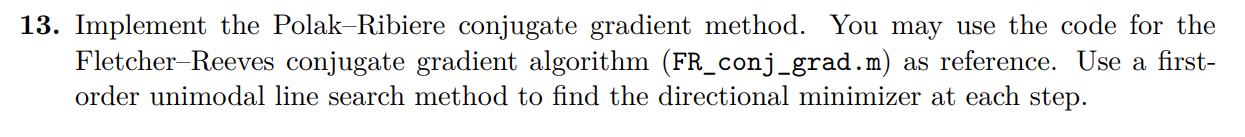

My first-order unimodal line search method of choice is the Bisection algorithm. Below is a demonstration on our simple unimodal function.

f = @(x) x.^3 - 3*x.^2 + 4;
df = @(x) 3*x.^2 - 6*x;
ddf = @(x) 6*x - 6;
plot_unimodal_method(@bisection_search, f, df, ddf, 20, 4, 0, 5, 256, 'Bisection Search');

### Functions

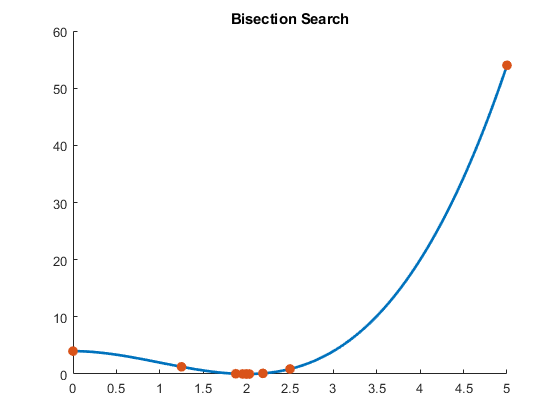

function x = plot_unimodal_method(G,f,df,ddf,testpts,startpt,a,b,res,ptitle)
    X = linspace(a,b,res);
    Y = f(X);
    

    x = G(f,df,ddf,startpt,a,b,20);
    
    figure; hold on;
    plot(X, Y, 'LineWidth', 2);
    plot(x, f(x), '.', 'MarkerFaceColor', 'auto', 'MarkerSize', 25);
    title(ptitle);
    hold off;
end

function [ x ] = bisection_search(f,df,~,~,a,b,iter) % A first-order bisection search implementation
    delta = [a b];
    eps = 0.0001;
    x = [a b];
    for i = 1:iter
        x_k = (delta(1) + delta(2)) / 2;
        dfx_k = df(x_k);
        if(abs(dfx_k) <= eps || i==iter)
            x = [x x_k];
        elseif(dfx_k > 0)
            delta = [delta(1) x_k];
            x = [x x_k];
        elseif(dfx_k < 0)
            delta = [x_k delta(2)];
            x = [x x_k];
        end
    end
end


function [ x ] = FR_conj_grad(f,df,~,x0,iter)
% f: vector->scalar objective function
% df: gradient function
% x0: starting point
% iter: number of iterations. Note that by "iteration", we refer to the
%    process of creating n=size(x0) potentially A-conjugate search
%    directions, i.e. it is essentially n optimization steps..

    eps=1e-12; % treshold for stability and directional minimization
    
    for k=1:iter
        x=x0;
        d = -df(x);
        % Initial search direction: steepest descent
        p = d;
        for i=1:size(x)
            if norm(d)>eps % avoid too small gradient to ensure stable computation of search dirs
                % Directional minimization; a really naive approach for
                % demonstrative purposes
                fdir=@(t) f(x+t*p);
                tmax=eps;
                while fdir(tmax)<fdir(tmax/2)
                    tmax=2*tmax; % expand until has at least one minimizer
                end
                gamma = zero_unimodal(fdir,0,0,0,0,tmax,log(eps/tmax)/log(2/3));
                % Go to the next point and compute the next search dir
                % using the Fletcher-Reeves formula
                x = x+gamma*p;
                beta = 1/(d'*d);
                d = -df(x);
                beta = beta*(d'*d);
                p = d+beta*p;
                % If p is not a descent direction (happens sometimes!) then choose its opposite
                if 0 > p'*d
                    p = -p;
                end
            end
        end
        x0=x;
    end
end